# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 4;
threshold = 0.6;

## Generate a random physical topology

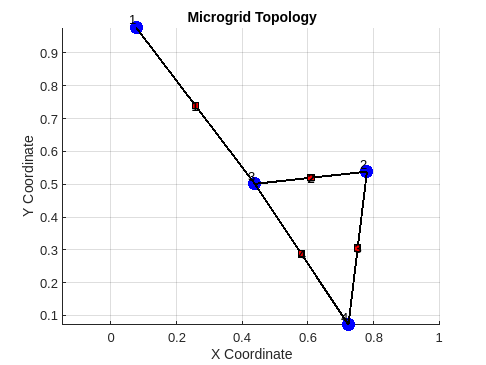

Coordinates of DGs:
    0.0763    0.9780
    0.7799    0.5385
    0.4384    0.5011
    0.7235    0.0721

Adjacency Matrix:
     0     0     1     0
     0     0     1     1
     1     1     0     1
     0     1     1     0

B_il Matrix:
     1     0     0     0
     0     1     1     0
    -1    -1     0     1
     0     0    -1    -1



% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.
% A = [A_ij]_{i,j} is the adgacency matrix of the DG-DG topology (N\times N)
[coords, A_ij, B_il] = generateMicrogridTopology(numOfDGs, threshold);


%%%% Update the figure to show the assumed initial communication topology
% (A_ij matrix representa the communication topology)



## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.02;      % Resistance
L0 = 0.01;      % Inductance
C0 = 22;    % Capacitance
RL0 = 0.3;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance
IL0 = 5;        % Constant Current Load
LoadNoiseMean = 10;
LoadNoiseStd = 2;


for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0,IL0,coords(i,:));
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i});
end


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 2;     % Line Resistance
Ll0 = 0.01;     % Line Inductance

numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l});
end

Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines A_ij B_il 
 % global DG Line B_il A_ij % Making some values as global variables

## Co-Design Process

parameters

BarGamma = 1000000;    % Fixed value for gammaBar
isSoft = 1;      % Set to 1 to avoid the hard graph constraint

% pScalar = 1/(numOfDGs+numOfLines);
piScalar = 10^2;
plScalar = 10^1;

piVals = piScalar*ones(1,numOfDGs);
plVals = plScalar*ones(1,numOfLines);

## 1. Centralized Local Controller Design

% Inside the function, you need to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 

First Method: This Method computes the passivity indices for DGs and lines at the same time. 

[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma,piVals,plVals) % topologyMetrics may be the B matrix 

Constraint "W_3" is satisfied by -3.4346e-09 .


W_val = 1.0e+04 *

    0.0100         0         0    0.0000   -0.0000   -0.0001         0         0         0
         0    0.0100         0   -0.0000    0.0056   -0.0006         0         0         0
         0         0    0.0100   -0.0001   -0.0006    0.0006         0         0         0
    0.0000   -0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001   -0.0000   -0.0000
   -0.0000    0.0056   -0.0006   -0.0001    3.7666   -0.0010   -0.0000    0.0027   -0.0003
   -0.0001   -0.0006    0.0006    0.0000   -0.0010    0.0002   -0.0000   -0.0003    0.0002
         0         0         0   -0.0001   -0.0000   -0.0000    0.0014         0         0
         0         0         0   -0.0000    0.0027   -0.0003         0    0.0014         0
         0         0         0   -0.0000   -0.0003    0.0002         0         0    0.0014


Constraint "W_1" is satisfied by -3.3472e-09 .


W_val = 1.0e+04 *

    0.0100         0         0    0.0000   -0.0000   -0.0001         0         0         0
         0    0.0100         0   -0.0000    0.0056   -0.0006         0         0         0
         0         0    0.0100   -0.0001   -0.0006    0.0006         0         0         0
    0.0000   -0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001   -0.0000   -0.0000
   -0.0000    0.0056   -0.0006   -0.0001    3.7688   -0.0010   -0.0000    0.0027   -0.0003
   -0.0001   -0.0006    0.0006    0.0000   -0.0010    0.0002   -0.0000   -0.0003    0.0002
         0         0         0   -0.0001   -0.0000   -0.0000    0.0014         0         0
         0         0         0   -0.0000    0.0027   -0.0003         0    0.0014         0
         0         0         0   -0.0000   -0.0003    0.0002         0         0    0.0014


Constraint "W_4" is satisfied by -3.2787e-09 .


W_val = 1.0e+04 *

    0.0100         0         0    0.0000   -0.0000   -0.0001         0         0         0
         0    0.0100         0   -0.0000    0.0055   -0.0006         0         0         0
         0         0    0.0100   -0.0001   -0.0006    0.0006         0         0         0
    0.0000   -0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001   -0.0000   -0.0000
   -0.0000    0.0055   -0.0006   -0.0001    3.7715   -0.0010   -0.0000    0.0026   -0.0003
   -0.0001   -0.0006    0.0006    0.0000   -0.0010    0.0002   -0.0000   -0.0003    0.0002
         0         0         0   -0.0001   -0.0000   -0.0000    0.0014         0         0
         0         0         0   -0.0000    0.0026   -0.0003         0    0.0014         0
         0         0         0   -0.0000   -0.0003    0.0002         0         0    0.0014


Constraint "W_2" is satisfied by -3.2156e-09 .


W_val = 1.0e+04 *

    0.0100         0         0    0.0000   -0.0000   -0.0001         0         0         0
         0    0.0100         0   -0.0000    0.0054   -0.0006         0         0         0
         0         0    0.0100   -0.0001   -0.0006    0.0006         0         0         0
    0.0000   -0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001   -0.0000   -0.0000
   -0.0000    0.0054   -0.0006   -0.0001    3.7743   -0.0010   -0.0000    0.0026   -0.0003
   -0.0001   -0.0006    0.0006    0.0000   -0.0010    0.0002   -0.0000   -0.0003    0.0002
         0         0         0   -0.0001   -0.0000   -0.0000    0.0014         0         0
         0         0         0   -0.0000    0.0026   -0.0003         0    0.0014         0
         0         0         0   -0.0000   -0.0003    0.0002         0         0    0.0014


Constraint "P_3" is satisfied by 9.0571e-08 .


W_val =     0.1514   -0.4719   -0.8128
   -0.4719   55.8800   -6.0447
   -0.8128   -6.0447    5.7524


Constraint "P_1" is satisfied by 9.0972e-08 .


W_val =     0.1516   -0.4664   -0.8116
   -0.4664   55.5763   -6.0543
   -0.8116   -6.0543    5.7299


Constraint "P_4" is satisfied by 9.2445e-08 .


W_val =     0.1521   -0.4558   -0.8090
   -0.4558   54.9881   -6.0720
   -0.8090   -6.0720    5.6858


Constraint "P_2" is satisfied by 9.3802e-08 .


W_val =     0.1525   -0.4440   -0.8060
   -0.4440   54.3393   -6.0908
   -0.8060   -6.0908    5.6362


Constraint "WBar_2" is satisfied by 5.4892e-07 .


W_val =     0.0012   -0.0000
   -0.0000    0.0010


Constraint "WBar_3" is satisfied by 5.5029e-07 .


W_val =     0.0012   -0.0000
   -0.0000    0.0010


Constraint "WBar_1" is satisfied by 5.5284e-07 .


W_val =     0.0012   -0.0000
   -0.0000    0.0010


Constraint "nuBar_2_high" is satisfied by 5.545e-07 .


W_val = -0.0010

Constraint "nuBar_3_high" is satisfied by 5.5596e-07 .


W_val = -0.0010

Constraint "WBar_4" is satisfied by 5.5799e-07 .


W_val =     0.0012   -0.0000
   -0.0000    0.0010


Constraint "nuBar_1_high" is satisfied by 5.5869e-07 .


W_val = -0.0010

Constraint "nuBar_4_high" is satisfied by 5.6458e-07 .


W_val = -0.0010

Constraint "rho_3_high" is satisfied by 3.5659e-06 .


W_val = 1.0000e+03

Constraint "rho_2_high" is satisfied by 3.5659e-06 .


W_val = 1.0000e+03

Constraint "rho_4_high" is satisfied by 3.5659e-06 .


W_val = 1.0000e+03

Constraint "rho_1_high" is satisfied by 3.5659e-06 .


W_val = 1.0000e+03

Constraint "rhoTilde_2_high2" is satisfied by 6.3154e-06 .


W_val = 100.0000

Constraint "rhoTilde_4_high2" is satisfied by 6.3455e-06 .


W_val = 100.0000

Constraint "rhoTilde_1_high2" is satisfied by 6.3795e-06 .


W_val = 100.0000

Constraint "rhoTilde_3_high2" is satisfied by 6.3813e-06 .


W_val = 100.0000

Constraint "rhoTilde_2_high1" is satisfied by 3.9948e-05 .


W_val = 100

Constraint "rhoTilde_4_high1" is satisfied by 4.1798e-05 .


W_val = 100

Constraint "rhoTilde_1_high1" is satisfied by 4.3933e-05 .


W_val = 100

Constraint "rhoTilde_3_high1" is satisfied by 4.5356e-05 .


W_val = 100

Constraint "PBar_1" is satisfied by 0.0063388 .


W_val = 0.0073

Constraint "PBar_3" is satisfied by 0.006387 .


W_val = 0.0074

Constraint "PBar_2" is satisfied by 0.0064538 .


W_val = 0.0075

Constraint "PBar_4" is satisfied by 0.0081896 .


W_val = 0.0092

Constraint "rhoBar_2_low2_2" is satisfied by 1.257 .


W_val = 0.7439

Constraint "rhoBar_2_low2_3" is satisfied by 1.257 .


W_val = 0.7438

Constraint "rhoBar_4_low2_3" is satisfied by 1.2586 .


W_val = 0.7438

Constraint "rhoBar_4_low2_4" is satisfied by 1.2586 .


W_val = 0.7438

Constraint "rhoBar_3_low2_2" is satisfied by 1.2586 .


W_val = 0.7439

Constraint "rhoBar_3_low2_4" is satisfied by 1.2587 .


W_val = 0.7438

Constraint "rhoBar_1_low2_1" is satisfied by 1.2616 .


W_val = 0.7438

Constraint "rhoBar_1_low2_3" is satisfied by 1.2616 .


W_val = 0.7438

Constraint "rhoBar_2_low1_2" is satisfied by 1.7134 .


W_val = 0.2874

Constraint "rhoBar_2_low1_3" is satisfied by 1.7134 .


W_val = 0.2874

Constraint "rhoBar_4_low1_4" is satisfied by 1.715 .


W_val = 0.2874

Constraint "rhoBar_3_low1_2" is satisfied by 1.715 .


W_val = 0.2874

Constraint "rhoBar_4_low1_3" is satisfied by 1.7151 .


W_val = 0.2874

Constraint "rhoBar_3_low1_4" is satisfied by 1.7151 .


W_val = 0.2874

Constraint "rhoBar_1_low1_1" is satisfied by 1.7181 .


W_val = 0.2874

Constraint "rhoBar_1_low1_3" is satisfied by 1.7181 .


W_val = 0.2874

Constraint "rhoBar_2low" is satisfied by 1.9998 .


W_val = 2.0008

Constraint "rhoBar_4low" is satisfied by 2.0014 .


W_val = 2.0024

Constraint "rhoBar_3low" is satisfied by 2.0015 .


W_val = 2.0025

Constraint "rhoBar_1low" is satisfied by 2.0045 .


W_val = 2.0055

Constraint "nu_2_low" is satisfied by 11.0864 .


W_val = -25.0000

Constraint "nu_4_low" is satisfied by 11.0885 .


W_val = -25.0000

Constraint "nu_1_low" is satisfied by 11.0894 .


W_val = -25.0000

Constraint "nu_3_low" is satisfied by 11.0901 .


W_val = -25.0000

Constraint "nu_3_high" is satisfied by 13.9089 .


W_val = -13.9099

Constraint "nu_1_high" is satisfied by 13.9096 .


W_val = -13.9106

Constraint "nu_4_high" is satisfied by 13.9105 .


W_val = -13.9115

Constraint "nu_2_high" is satisfied by 13.9126 .


W_val = -13.9136

Constraint "rho_3_receprocity" is satisfied by 99.9988 .


W_val = 1.0e+03 *

    1.0000    0.0010
    0.0010    0.1000


Constraint "rho_1_receprocity" is satisfied by 99.9988 .


W_val = 1.0e+03 *

    1.0000    0.0010
    0.0010    0.1000


Constraint "rho_4_receprocity" is satisfied by 99.9988 .


W_val = 1.0e+03 *

    1.0000    0.0010
    0.0010    0.1000


Constraint "rho_2_receprocity" is satisfied by 99.9988 .


W_val = 1.0e+03 *

    1.0000    0.0010
    0.0010    0.1000


Constraint "rhoTilde_3_low" is satisfied by 99.999 .


W_val = 100.0000

Constraint "rhoTilde_1_low" is satisfied by 99.999 .


W_val = 100.0000

Constraint "rhoTilde_4_low" is satisfied by 99.999 .


W_val = 100.0000

Constraint "rhoTilde_2_low" is satisfied by 99.999 .


W_val = 100.0000

Constraint "rho_1_low" is satisfied by 1000 .


W_val = 2.5000e-05

Constraint "rho_2_low" is satisfied by 1000 .


W_val = 2.5000e-05

Constraint "rho_4_low" is satisfied by 1000 .


W_val = 2.5000e-05

Constraint "rho_3_low" is satisfied by 1000 .


W_val = 2.5000e-05

Constraint "gammaTilde_3_low" is satisfied by 2499.998 .


W_val = 2.5000e+03

Constraint "gammaTilde_1_low" is satisfied by 2499.9981 .


W_val = 2.5000e+03

Constraint "gammaTilde_4_low" is satisfied by 2499.9981 .


W_val = 2.5000e+03

Constraint "gammaTilde_2_low" is satisfied by 2499.9982 .


W_val = 2.5000e+03

Constraint "nuBar_4_low_4" is satisfied by 9999.999 .


W_val = -1.0000e+04

Constraint "nuBar_4_low_3" is satisfied by 9999.999 .


W_val = -1.0000e+04

Constraint "nuBar_1_low_1" is satisfied by 9999.999 .


W_val = -1.0000e+04

Constraint "nuBar_1_low_3" is satisfied by 9999.999 .


W_val = -1.0000e+04

Constraint "nuBar_3_low_2" is satisfied by 9999.999 .


W_val = -1.0000e+04

Constraint "nuBar_3_low_4" is satisfied by 9999.999 .


W_val = -1.0000e+04

Constraint "nuBar_2_low_2" is satisfied by 9999.999 .


W_val = -1.0000e+04

Constraint "nuBar_2_low_3" is satisfied by 9999.999 .


W_val = -1.0000e+04

Constraint "gammaTilde_2_high" is satisfied by 997500.0008 .


W_val = 2.5000e+03

Constraint "gammaTilde_4_high" is satisfied by 997500.0009 .


W_val = 2.5000e+03

Constraint "gammaTilde_1_high" is satisfied by 997500.0009 .


W_val = 2.5000e+03

Constraint "gammaTilde_3_high" is satisfied by 997500.001 .


W_val = 2.5000e+03

del2_il = 0.0990

del3 = 69.6816

del2_il = 0.0990

del3 = 69.5063

del2_il = 0.0990

del3 = 69.5646

del2_il = 0.0990

del3 = 69.6848

del2_il = 0.0990

del3 = 69.5231

del2_il = 0.0990

del3 = 69.5794

del2_il = 0.0990

del3 = 69.5703

del2_il = 0.0990

del3 = 69.5682

DG = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusLocalController = logical
   1


Second Method: This method first computes the DGs' passivity indices and use those properties to compute the Lines' passivity indices. 

% [DG, rhoTilde_i, nu_i, gammaTilde_i,statusDG] = designDGPassivity(DG, B_il,piVals);
% [Line, statusLine] = designLinePassivity(Line, DG, B_il, BarGamma, piVals,plVals,rhoTilde_i, nu_i);
%%%% Theoretically explain why this works in the paper, in a corollary (of Theorem 2).  
%%%% There is an imbalance


DG{1}

ans = struct with fields:
              R: 0.0227
              L: 0.0150
              C: 22.0007
              Y: 3.2464
             IL: 5.0381
              A: [3×3 double]
              B: [3×1 double]
    coordinates: [0.0763 0.9780]
             P0: [3×3 double]
             K0: [-7.3918e+03 -204.7402 -1.2634e+03]
             nu: -13.9106
            rho: 0.0100
    gammaTilde0: 2.5000e+03


Line{1}

ans = struct with fields:
      R: 2.0067
      L: 0.0147
      A: -136.7185
      B: 68.1314
     P0: 0.0073
     nu: -0.0010
    rho: 2.0055



Del = Line{1}.nu/DG{1}.rho  -Line{1}.rho*(DG{1}.C)^2/DG{1}.nu

Del = 69.6816


% ((-nu_l)/rho_i) < (rho_l/(-nu_i))C_ti^2
% 60/1 < 250/12

## 2. Global Controller Design

% Initialized nominal and reference voltages
V_nom = 120;            % Nominal Voltage
V_ref = 48;             % Reference Voltage

% Scenario #1: Global Load Change
R_Global = 5;           % Global Load
ChangeGlobalLoad1 = 1;  % Connect Global Load #2
ChangeGlobalLoad2 = 3;  % Disconnect Global Load #2

% Scenario #2: Plug-and-Play 
PlugOut = 2;            % Plug out DG #4
PlugIn = 4;             % Plug in DG #4

% Scenario #3: Change of Reference Voltage:
V_ref1 = 48;
V_ref2 = 100;
change_reference = 4;


[DG,Line,statusGlobalController,gammaTildeVal,K,C,BarC,H,P_iVal,P_lVal] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft)

Constraint "Q_Structure" is satisfied by -1.767e-11 .
Constraint "W" is satisfied by 1.3112e-09 .
Constraint "W_Temp_1" is satisfied by 1.5958e-09 .
Constraint "W_Temp_4" is satisfied by 0.42774 .
Constraint "W_Temp_3" is satisfied by 3.3279 .
Constraint "PBar_44" is satisfied by 7.3501 .
Constraint "PBar_22" is satisfied by 7.3511 .
Constraint "PBar_33" is satisfied by 7.5075 .
Constraint "PBar_11" is satisfied by 7.5497 .
Constraint "P_22" is satisfied by 100 .
Constraint "P_44" is satisfied by 100 .
Constraint "P_11" is satisfied by 100 .
Constraint "P_33" is satisfied by 100 .
Constraint "W_Temp_1" is satisfied by 447.9635 .
Constraint "gammaTilde_low" is satisfied by 2499.998 .
Constraint "gammaTilde_high" is satisfied by 997500.002 .


Mat_1Eigs = 1.0e+03 *

    1.3910
    1.3910
    1.3910
    1.3911
    1.3911
    1.3911
    1.3911
    1.3911
    1.3911
    1.3914


Mat_2Eigs = 1.0e+03 *

    0.0000
    0.0000
    0.0000
    0.0000
    1.3910
    1.3910
    1.3910
    1.3911
    1.3911
    1.3911


Mat_3Eigs = 1.0e+03 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0010
    0.0010
    0.0010
    0.0010
    1.3910
    1.3910


Mat_4Eigs = 1.0e+03 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0010
    0.0010


Mat_44Eigs =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    7.0430
    7.0588


Mat_4_Test1Eigs = 1.0e+03 *

    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0019
    0.0019


Mat_4_Test2Eigs =     0.0072
    0.0073
    0.0074
    0.0075
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0001


Mat_4_Test3Eigs =     0.0000
    0.0000
    0.0000
    0.0000
    1.0000
    1.0000
    1.0000
    1.0000
    2.0000
    2.0000


ans =   100.0000         0         0         0
         0  100.0000         0         0
         0         0  100.0000         0
         0         0         0  100.0000


ans =     7.5497         0         0         0
         0    7.3511         0         0
         0         0    7.5075         0
         0         0         0    7.3501


GammaMat = 1.0e+03 *

    2.5000         0         0         0
         0    2.5000         0         0
         0         0    2.5000         0
         0         0         0    2.5000


ans = 2.5000e+03

Mat_5Eigs = 1.0e+03 *

   -0.0009
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Mat_55Eigs =    14.7083
   14.7180
   15.0337
   15.1405


Mat_5_Test1Eigs = 1.0e+03 *

    0.0033
    0.0063
    0.0121
    0.0148
    1.3910
    1.3910
    1.3911
    1.3911
    1.3911
    1.3911


Mat_5_Test2Eigs =     0.4277
    0.5579
    0.8480
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    7.0430
    7.0588


Mat_6Eigs = 1.0e+03 *

   -0.0112
   -0.0056
   -0.0016
   -0.0016
   -0.0016
   -0.0016
   -0.0014
   -0.0012
   -0.0005
    0.0000


Mat_66Eigs = 1.0e+03 *

    2.5000
    2.5000
    2.5000
    2.5000
    2.5000
    2.5000
    2.5000
    2.5000
    2.5000
    2.5000


Mat_6_Test1Eigs = 1.0e+03 *

    0.4480
    0.4480
    0.4480
    0.4480
    0.4480
    0.4480
    0.4480
    0.4480
    0.4480
    0.4481


Mat_6_Test2Eigs = 1.0e+03 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0060
    0.0061


DG = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusGlobalController = logical
   1


gammaTildeVal = 2.5000e+03

K = 4×4 cell array
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}


C =      1     0     0     0     0     0    -1     0     0     0     0     0
     0     0     0     1     0     0    -1     0     0     0     0     0
     0     0     0     1     0     0     0     0     0    -1     0     0
     0     0     0     0     0     0     1     0     0    -1     0     0


BarC =    -0.0455         0         0         0
         0         0         0         0
         0         0         0         0
         0   -0.0455   -0.0455         0
         0         0         0         0
         0         0         0         0
    0.0455    0.0455         0   -0.0455
         0         0         0         0
         0         0         0         0
         0         0    0.0455    0.0455


H =      0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1


P_iVal =   100.0000
  100.0000
  100.0000
  100.0000


P_lVal =     7.5497
    7.3511
    7.5075
    7.3501


%%%% Theoretically think about adding cormalizing constraints trace(P_i)==1, trace(P_l)==1 constraint

K{1,1}

ans =          0         0         0
         0   -0.0607         0
         0         0         0


K{4,4}

ans =          0         0         0
         0   -0.0606         0
         0         0         0



% AT the local controller, instead of adding xconstraints, what if we added
% them as soft constraints in the objective?
% SImilarly, we can bias the global controller design by selecting its
% objective

#### The following functions are desgined to evaluate the effects of different parameters on the passivity indices of DGs and lines and their feasibilities

Optimize pVals (Method 1: Qucik and Dirty, Run this in a seperate .m file - to get faster result) 

% See the 'OptimizepValsMethod1.m' file. 

Optimize pVals (Method 2: Use Matlab 'fmincon')

% [piVals, plVals] = optimizeCodesignParameters()

Optimize pVals (Method 3)

You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in model (<a href="yalmip.github.io/naninmodel">learn to debug</a>)
You have NaNs in

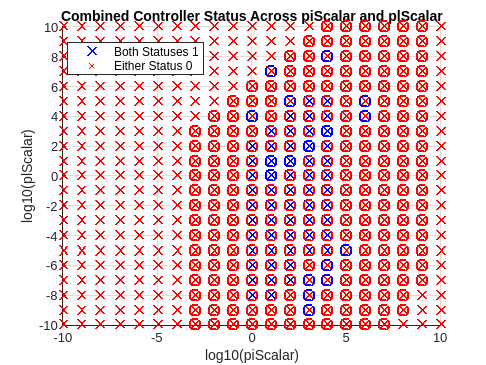

% plotLocalControlDesign(DG, Line, B_il, BarGamma, numOfDGs, numOfLines);
% hold on
% plotGlobalControlDesign(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);

plotCombinedControlDesign(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);

% plotTestBothFeasibility(DG, Line, B_il, BarGamma, A_ij, isSoft, numOfDGs, numOfLines);

Function to evaluate the effect of number of DGs and Threshold

% numDGsRange = 5:6;              % Example range for number of DGs
% thresholdRange = 0.1:0.1:1;     % Example range for threshold values
% pScalarRange = 0.01:0.01:10;    % Example range for pScalar values
% BarGamma = 5;                   % Fixed value for gammaBar
% isSoft = 1;                     % Set to 1 to use soft constraint
% 
% [numOfDGs, threshold] = evaluateDesigns(numDGsRange, thresholdRange, BarGamma, pScalarRange, isSoft);